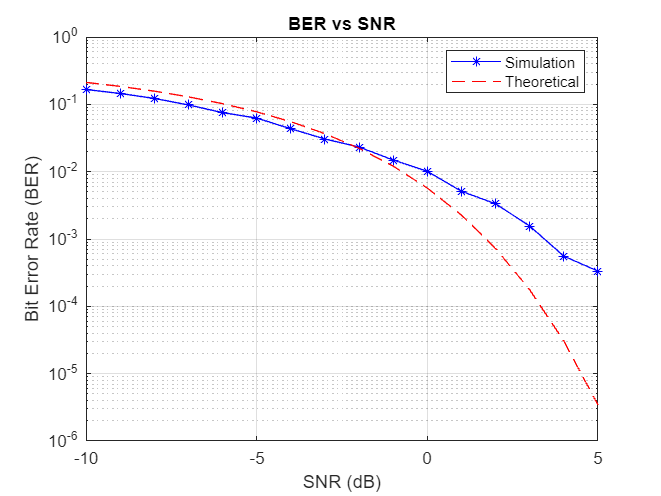

% Parameters
Tb = 1e-4 ;% Bit duration of 1 ms
N = 9000; % Number of bits for better BER estimation
Fs = 1e6; % Sampling frequency of 1 MHz for better resolution
fn1 = 30e3; % Frequency for bit '1'
fn2 = 40e3; % Frequency for bit '0'

% Generate random bit sequence of length N
data = randi([0, 1], 1, N);

% Time vector for one bit duration
t = 0:1/Fs:Tb-(1/Fs);

% Environmental parameters
T = 15; % Temperature in degrees Celsius
S = 35; % Salinity in parts per thousand
D = 100; % Depth in meters
pH = 8; % pH of the water

% Calculate attenuation for both frequencies
alpha1 = ainslie_mccolm_attenuation(fn1 / 1000, T, S, D, pH); % Convert to kHz
alpha2 = ainslie_mccolm_attenuation(fn2 / 1000, T, S, D, pH); % Convert to kHz
alpha_avg = (alpha1 + alpha2) / 2;

% Initialize the modulated signal
AM_signal = [];

% Loop through each bit
for bit = data
    if bit == 1
        Pn_t = sin(2*pi*(fn2-fn1)/Tb*t + 2*pi*fn1*t);
    else
        Pn_t = sin(2*pi*(fn1-fn2)/Tb*t + 2*pi*fn2*t);
    end
    % Append to the modulated signal
    AM_signal = [AM_signal, Pn_t];
end

% Apply attenuation to the AM signal
attenuated_AM_signal = AM_signal * 10^(-alpha_avg * D / 20);

% SNR range for the simulation
SNR_dB = -10:1:5; % SNR values in dB
BER = zeros(size(SNR_dB)); % Initialize BER array

% Loop over each SNR value
for i = 1:length(SNR_dB)
    % Add noise to the attenuated AM signal using awgn function
    noisy_AM_signal = awgn(attenuated_AM_signal, SNR_dB(i), 'measured');
    
    % Bandpass filter design to pass frequencies between 22 kHz and 38 kHz
    bpFilt = designfilt('bandpassiir', ...
        'FilterOrder', 8, ...
        'HalfPowerFrequency1', 22e3, ...
        'HalfPowerFrequency2', 38e3, ...
        'SampleRate', Fs);
    
    % Apply the bandpass filter to the noisy AM signal
    filtered_AM_signal = filtfilt(bpFilt, noisy_AM_signal);
    
    % Detect using AM
    [AM_bits, ~, ~] = detect_AM(filtered_AM_signal, Fs, Tb, fn1, fn2);
    
    % Calculate Bit Error Rate (BER)
    num_errors = sum(data ~= AM_bits);
    BER(i) = num_errors / length(data);
end
% Theoretical BER calculation (assuming BPSK in AWGN)
theoretical_BER = qfunc(2*sqrt(1.6*(10.^(SNR_dB / 10))));

% Plot BER vs SNR
figure;
semilogy(SNR_dB, BER, 'b*-', 'DisplayName', 'Simulation');
hold on;
semilogy(SNR_dB, theoretical_BER, 'r--', 'DisplayName', 'Theoretical');
title('BER vs SNR');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
legend;
grid on;



% Supporting functions


function alpha = ainslie_mccolm_attenuation(f, T, S, D, pH)
    % f is frequency in kHz
    f1 = 0.78 * sqrt(S / 35) * exp(T / 26);
    f2 = 42 * exp(T / 17);

    term1 = 0.106 * (f1^2 * f^2) / (f1^2 + f^2) * exp((pH - 8) / 0.56);
    term2 = 0.52 * (1 + T / 43) * (S / 35) * (f2^2 * f^2) / (f2^2 + f^2) * exp(-D / 6);
    term3 = 4.9e-4 * f^2 * exp(-D / 17) * (T / 27);
    
    alpha = term1 + term2 + term3;
end

function [AM_detected, corr1_output, corr2_output] = detect_AM(received_signal, Fs, Tb, fn1, fn2)
    % Constants
    bit_samples = round(Tb * Fs); % Number of samples per bit

    % Create time vector for one bit duration
    t = (0:bit_samples-1) / Fs;

    % Generate reference signals for bit '1' and bit '0'
    ref1 = sin(2*pi*(fn2-fn1)/Tb*t + 2*pi*fn1*t); % AM for bit '1'
    ref0 = sin(2*pi*(fn1-fn2)/Tb*t + 2*pi*fn2*t); % AM for bit '0'

    % Initialize detected bits array
    AM_detected = zeros(1, length(received_signal) / bit_samples);

    % Initialize correlation outputs
    corr1_output = zeros(1, length(AM_detected));
    corr2_output = zeros(1, length(AM_detected));

    % Perform matched filtering and energy detection
    for k = 1:length(AM_detected)
        start_idx = (k-1) * bit_samples + 1;
        end_idx = k * bit_samples;

        % Extract current bit segment
        segment = received_signal(start_idx:end_idx);

        % Compute correlation with reference signals
        corr1 = sum(segment .* ref1);
        corr2 = sum(segment .* ref0);

        % Store correlation outputs for plotting
        corr1_output(k) = corr1;
        corr2_output(k) = corr2;

        % Energy detection (using absolute values to avoid negative energies)
        energy1 = abs(corr1);
        energy2 = abs(corr2);

        % Determine bit based on maximum energy
        if energy1 > energy2
            AM_detected(k) = 1;
        else
            AM_detected(k) = 0;
        end
    end
end
